addpath('..\..\scripts'); warning off;
load variants.mat
%CDC_sero;
data_4_s = smooth_epidata(data_4, 14);


cid = 1;

ii = [0 diff(data_4_s(cid, :))];
var_data = squeeze(red_var_matrix(cid, valid_lins(cid, :)>0, :));
maxt = size(data_4, 2);
val_times = find(valid_times(cid, 1:end)>0); val_times(val_times< (maxt - 100)) = [];

ii = ii(val_times)'; %ii = smooth(ii);
var_data = var_data(:, val_times);
ig_idx = sum(var_data, 2)./sum(sum(var_data, 2)) <=0; var_data(ig_idx, :) = [];
these_lins = lineages((valid_lins(cid, :)>0)); these_lins(ig_idx) = [];
nv = size(var_data, 1);
T = size(var_data, 2);
base_var = find(strcmpi(these_lins, 'b.1.1.7'));
%goodX = squeeze(var_frac_all(cid, valid_lins(cid, :)>0, val_times));
goodX = squeeze(all_var_est_matrix(cid, valid_lins(cid, :)>0, val_times));
goodX = fillmissing(goodX, 'previous', 2);
goodX = movmean(var_data./sum(var_data), 14, 2);

## Model Free

% options = optimoptions('fminunc', "Algorithm","quasi-newton", "Display", 'iter'...
%     ,'MaxFunctionEvaluations',10000); %, 'SpecifyObjectiveGradient',true);
%
% [X,fval,exitflag,output,grad,hessian]= fminunc(@(X)(model_free_obj(X, var_data)), log(goodX + 1e-10), options);
% Yhat = exp(X); Yhat = Yhat./sum(Yhat, 1);


## LSQNONLIN Method


% options = optimoptions(@lsqnonlin, 'MaxFunctionEvaluation', 10000, "Algorithm", "levenberg-marquardt", ...
%     'Display','iter'); % , 'SpecifyObjectiveGradient',true, 'SpecifyConstraintGradient',true); %, 'CheckGradients', true);
%
%
% init_val = [(goodX(:, end)); zeros(nv-1, 1); ones(nv-1, 1)];
% lb = [(1e-10)*ones(nv, 1); -1*inf(nv-1, 1); 0.1 + zeros(nv-1, 1)]; lb(base_var) = init_base(end);
% ub = [ones(nv, 1); inf(nv-1, 1); 10 + zeros(nv-1, 1);]; ub(base_var) = init_base(end);
% init_base = goodX(base_var, :);
% X = lsqnonlin(@(X)(multi_variant_implicit_obj(X, var_data, val_times, ii, 2, base_var, init_base)), init_val, lb, ub, options);
% [nLL, Yhat, err_mat, Y0, R0, R1] = multi_variant_implicit_obj(X, var_data, val_times, ii, 1, base_var, init_base);
%
% ii1 = [0 diff(data_4_s(cid, :))]*un_array(cid, 2);
% [Yhat1, Y0, R0, R1] = multi_variant_implicit_obj_ex(X, (1:length(ii1)), ii1, base_var);
%
% fprintf('.');
% catch
%     disp('Error');
% end


## FMINCON Method

options = optimoptions('fmincon',"Algorithm","interior-point", 'Display', "final", 'MaxIterations', 20000, ...
    'MaxFunctionEvaluations', 10000, 'SpecifyObjectiveGradient',true, 'SpecifyConstraintGradient',true);
%init_val = [ones(nv, 1)/nv; zeros(nv-1, 1); ones(nv-1, 1); rand(length(val_times), 1)];
options_unc = optimoptions('fminunc', 'MaxFunctionEvaluations', 10000, 'Display', 'iter', 'SpecifyObjectiveGradient', true);

cid = 1;
    
    ii1 = [0 diff(data_4_s(cid, :))];
    var_data = squeeze(red_var_matrix(cid, valid_lins(cid, :)>0, :));
    
    val_times = find(valid_times(cid, 1:end)>0); val_times(val_times< (maxt - 70)) = [];
    
    ii = ii1(val_times)'; %ii = smooth(ii);
    var_data = var_data(:, val_times);
    ig_idx = sum(var_data, 2) < 1; var_data(ig_idx, :) = [];
    these_lins = lineages((valid_lins(cid, :)>0)); these_lins(ig_idx) = [];
    nv = size(var_data, 1);
    T = size(var_data, 2);
    base_var = find(strcmpi(these_lins, 'b.1.1.7'));
    
%     %goodX = squeeze(var_frac_all(cid, valid_lins(cid, :)>0, val_times));
%     % goodX = squeeze(all_var_est_matrix(cid, valid_lins(cid, :)>0, val_times));
%     % goodX = fillmissing(goodX, 'previous', 2);
%     goodX = movmean(var_data./sum(var_data), 14, 2);
%     
%     init_val = [max(goodX(:, 1), 1e-20); zeros(nv-1, 1); ones(nv-1, 1); (goodX(base_var, :)')];
%     lb = [(1e-20)*ones(nv, 1); -2*ones(nv-1, 1); 0.2 + zeros(nv-1, 1); 1e-20 + zeros(T, 1)];
%     ub = [ones(nv, 1); 2*ones(nv-1, 1); 30*ones(nv-1, 1); ones(T, 1)];
%     
%     Aeq = zeros(1, length(lb)); Aeq(1:nv) = 1; beq = 1;
%     A = zeros(2*(nv-1), length(lb)); b = zeros(2*(nv-1), 1);
%     for jj=1:nv-1
%         A(jj, nv + jj) = 1; A(jj, nv + jj + nv-1) = -1;
%         A(jj+nv-1, nv + jj) = -7; A(jj + nv-1, nv + jj + nv-1) = 1; b(jj+nv-1) = 7;
%     end
 
            ii1(ii1<1) = 1; ii1 = ii1(:);
 %   [X,fval,exitflag,output,lambda,grad,hessian] = fmincon(@(X)(multi_variant_obj_d(X, var_data, val_times, ii, 0, base_var)), ...
 %           init_val, A, b, Aeq, beq, lb, ub,...
 %           @(X)(multi_variant_cons_d(X, var_data, val_times, ii, base_var)), options);
 
%        [Yhat1, Y0, R0, R1] = multi_variant_implicit_obj_ex(X, (1:length(ii1)), ii1, base_var, size(var_data, 1), val_times(1));
 
    [x,fval,exitflag,output,grad,hessian] = fminunc(@(Y)(multi_variant_imp_obj_d(Y, var_data, val_times, ii, base_var,30 )), rand(3*(nv-1), 1), options_unc);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          16720.9                      6.36e+03
     1           2           9606.9    0.000157151       6.91e+03  
     2           3          8780.89              1       2.63e+03  
     3           4          7912.76              1       2.29e+03  
     4           6          7449.23       0.497737       1.16e+03  
     5           7          7388.63              1            909  
     6           8          7356.92              1            253  
     7           9          7319.51              1            290  
     8          10          7135.84              1       1.45e+03  
     9          11          6958.16              1       1.97e+03  
    10          12             6851              1       6.14e+03  
    11          14          6735.72       0.338858       1.39e+03  
    12          15          6673.61              

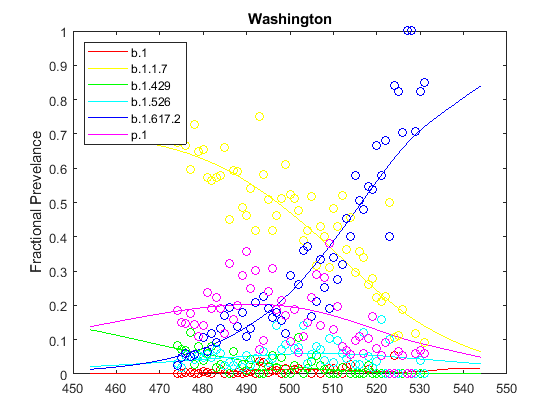

    [nLL, G, Yhat1, Y0, R0, R1] = multi_variant_imp_obj_d(x, [], (1:length(ii1)), ii1, base_var, val_times(30));    


        tvals = (val_times(1) - 20):length(ii1);
        figure; h1 = plot(tvals, Yhat1(:, tvals)'); hold on; h2 = plot(val_times, (var_data./sum(var_data, 1))', 'o'); hold off;
        set(h1, {'color'}, num2cell(hsv(size(var_data, 1)),2)); set(h2, {'color'}, num2cell(hsv(size(var_data, 1)),2));
        ylabel('Fractional Prevelance');
        legend(these_lins, 'location', 'northwest'); title(countries{cid})

for cid = 1:56
    if flag_list ~= 1
        continue;
    end
    
    if sum(valid_lins(cid, :)>0) < 3
        continue;
    end
    
    val_times = find(valid_times(cid, 1:end)>0); val_times(val_times< (maxt - 70)) = [];
    var_data = squeeze(red_var_matrix(cid, valid_lins(cid, :)>0, :));
    ii = [0 diff(data_4_s(cid, :))]*un_array(cid, 2);
    ii = ii(val_times)'; %ii = smooth(ii);
    var_data = var_data(:, val_times);
    ig_idx = sum(var_data, 2)./sum(sum(var_data, 2)) <0; var_data(ig_idx, :) = [];
    these_lins = lineages((valid_lins(cid, :)>0)); these_lins(ig_idx) = [];
    
    nv = size(var_data, 1);
    T = size(var_data, 2);
    base_var = find(strcmpi(these_lins, 'b.1.1.7'));
    R0 = R0_mat(cid, valid_lins(cid, :)>0);
    R1 = R1_mat(cid, valid_lins(cid, :)>0);
    Y0 = Y0_mat(cid, valid_lins(cid, :)>0);
    X = X_cell{cid};
    high_lins = find((R0./R1 > 1e-4));
    
    if length(high_lins) == 0 ||  isempty(base_var)
        continue;
    end
    
    [nLL, G, Yhat, Y0, R0, R1] = multi_variant_obj_d(X, var_data, val_times, ii, 0, base_var);
    Yhat1 = squeeze(new_var_frac_all(cid, (valid_lins(cid, :)>0), :));
    tvals = (val_times(1) - 20):size(data_4, 2);
    figure; h1 = semilogy(tvals, (Yhat1(high_lins, tvals)./Yhat1(base_var, tvals))'); hold on; h2 = semilogy(val_times, (var_data(high_lins, :)./var_data(base_var, :))', 'o'); hold off;
    set(h1, {'color'}, num2cell(hsv(length(high_lins)),2)); set(h2, {'color'}, num2cell(hsv(length(high_lins)),2));
    ylim([0.01, Inf]);
    title(countries{cid}); legend(these_lins(high_lins), 'Location','northwest');
    
end

Unrecognized function or variable 'flag_list'.


all_variants_us_forecasts;

......................................................................Files Written


## Relative growth rate advantage

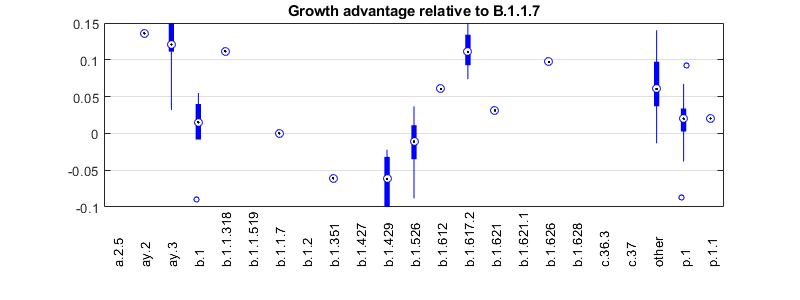

figure; set(gcf, 'position', [10 10 800 300]);
base_lin = strcmp(lineages, 'b.1.1.7');
boxplot((rel_adv - rel_adv(:, base_lin)), lineages, 'PlotStyle',"compact");
ylim([-0.1 0.15]); set(gca, 'YGrid','on')

title('Growth advantage relative to B.1.1.7');

## Calculate R values

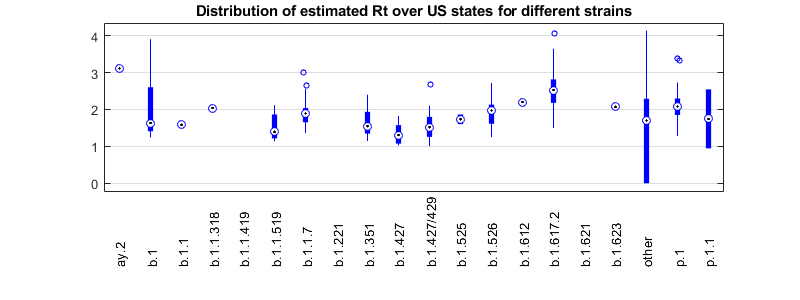

Rt_all = nan(ns, length(lineages));
for l=1:length(lineages)
    Rt = calc_Rt(all_betas{l}, best_param_list_v(:, 1), best_param_list_v(:, 2), ones(ns, 1));
    Rt_all(valid_lins(:, l)>0, l) = Rt(valid_lins(:, l)>0);
end

figure; set(gcf, 'position', [10 10 800 300]);
boxplot(Rt_all, lineages, 'PlotStyle',"compact");
title('Distribution of estimated Rt over US states for different strains');
set(gca, 'YGrid','on')

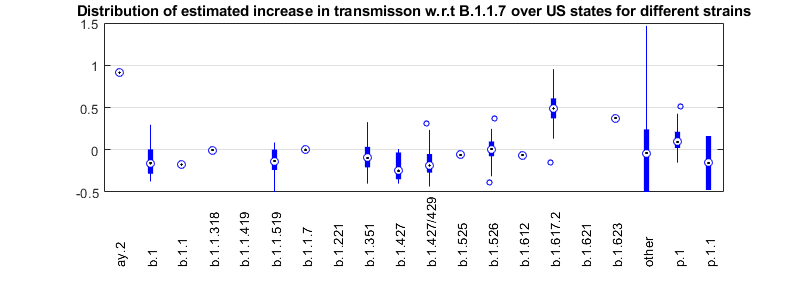


figure; set(gcf, 'position', [10 10 800 300]);
Rt_adv = Rt_all./Rt_all(:, base_lin);
boxplot(Rt_adv-1, lineages, 'PlotStyle',"compact");
set(gca, 'YGrid','on')
title('Distribution of estimated increase in transmisson w.r.t B.1.1.7 over US states for different strains');
ylim([-0.5, 1.5])

## Estimated Prevelance

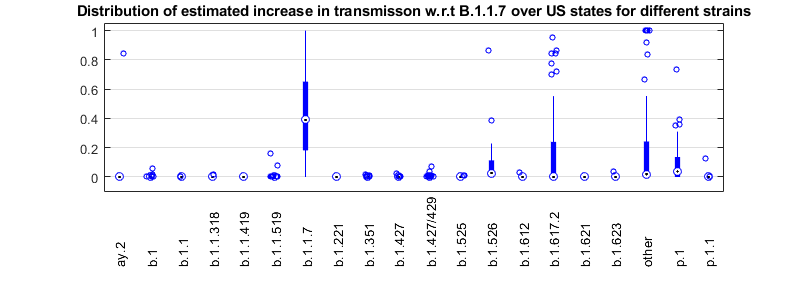

figure; set(gcf, 'position', [10 10 800 300]);
boxplot(squeeze(var_frac_all(:, :, end-4)), lineages, 'PlotStyle',"compact");
set(gca, 'YGrid','on')
title('Distribution of estimated increase in transmisson w.r.t B.1.1.7 over US states for different strains');

## Regions with forecast of increase in new cases

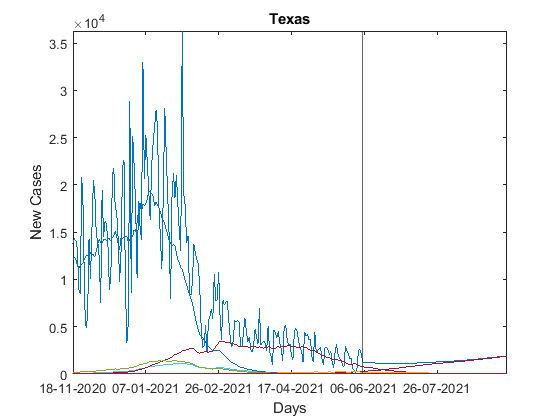

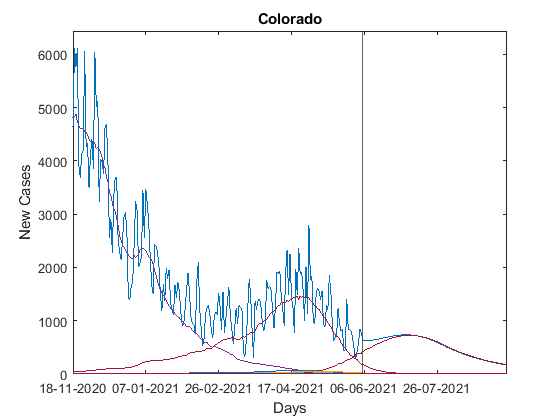

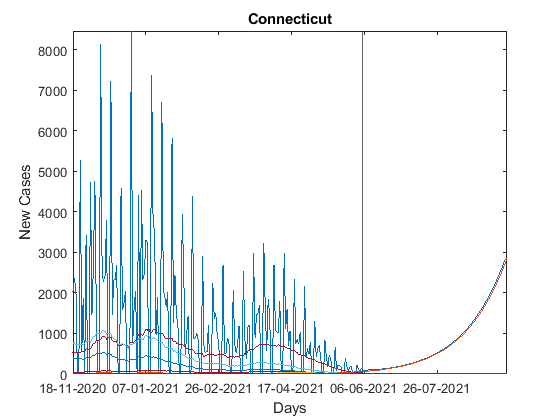

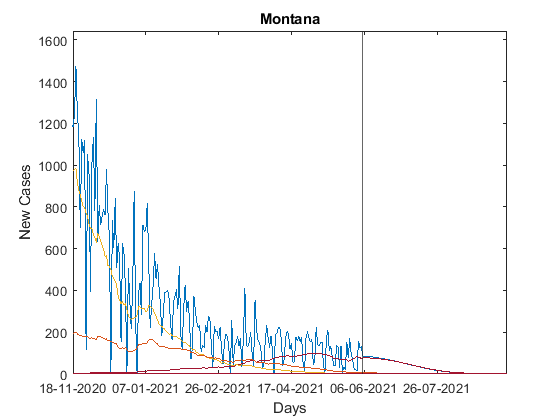

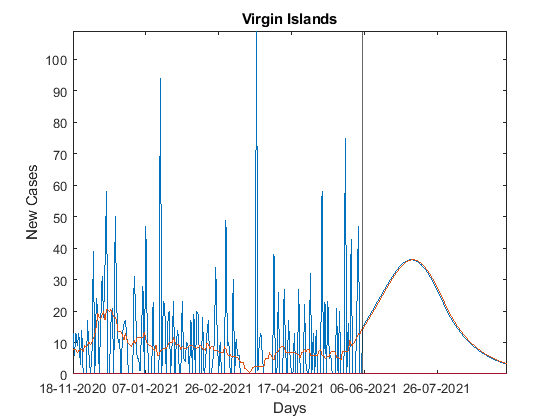

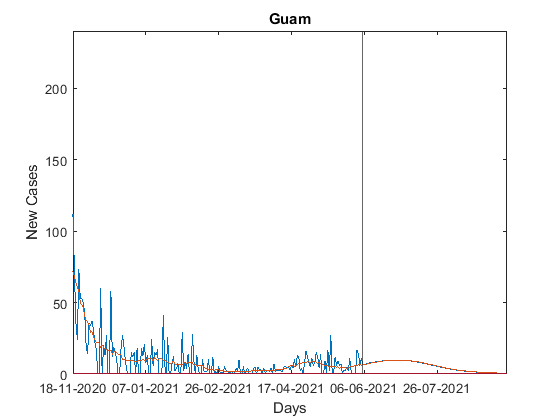

ridx = (find(any(diff(infec_un_0')' > (data_4_s(:, end)-data_4_s(:, end-7))/7, 2)));

for ii=1:length(ridx)
    figure;
    cid = ridx(ii); plot([diff(data_4(cid, :)) diff(infec_un_0(cid, :))]);
    hold on;  plot(diff(squeeze(all_data_vars_matrix(cid, :, :))')); xline(thisday);
    title(countries{ridx(ii)}); xlabel('Days'); ylabel('New Cases');
    xlim([300, Inf]);
    ylim([0, Inf]);
    
    ax = gca;
    ax.XTickLabel = datestr(caldays(ax.XTick) + datetime(2020, 1, 23), 'dd-mm-yyyy');
    hold off
end